### Set Up

clear; close all
load BigNetworkExperimentsBetaSkeleton.mat

s = zeros(numNode,1);
dNode = 1000;
s(oNode)=1;
s(dNode)=-1;

B=zeros(numNode,numEdge);
listEdge = (1:numEdge)';
sNode = G.Edges.EndNodes(:,1);
tNode = G.Edges.EndNodes(:,2);
B(sub2ind(size(B), sNode, listEdge)) = 1;
B(sub2ind(size(B), tNode, listEdge)) = -1;

### You should certainly ensure that the peak Price of Anarchy (PoA) is captured — and this may require you to also compute the System Optimal (SO) assignment

Price of anarchy can be defined as:


$$$PoA := \frac{f_{UE}}{f_{SO}} $$$


Therefore it was neccessary to compute the UE and SO assignments before comparing their total system costs.

% Parameters
dValues = 1.6:0.02:2;  % Demand levels from 0 to 100 in steps of 20
numSteps = length(dValues); % Number of demand steps

% Preallocate space for storing link flows
linkFlows = zeros(numEdge, numSteps);

% Set up the optimization problem
Aeq = B;                % Node conservation matrix
A = [];                 % No inequality constraints
bvec = [];              % No inequality constraints
LB = zeros(numEdge, 1); % Lower bound for link flows
UB = [];                % No upper bounds

% finding UE and SO values for each demand plot side by side
% intialising storage arrays for System Cost Value and PoA
PoA_arr = zeros(numSteps, 1);
Sys_Cost = zeros(numSteps,2);

% Loop through each demand value
tic
for i = 1:numSteps
    d = dValues(i);
    beq = d * s;        % Scale the demand vector
    H = diag(b);        % Quadratic term for the Beckmann functional
    f = a;
    [x_UE, f_UE, ef_UE, x_SO, f_SO, ef_SO, PoA] = Price_of_Anarchy(H, f, A, bvec, Aeq, beq, LB, UB);
    % Store the link flows
    linkFlows(:, i, 1) = x_UE;
    linkFlows(:, i, 2) = x_SO;

    % store system costs and PoA
    Sys_Cost(i,:) = [f_UE, f_SO];
    PoA_arr(i) = PoA;
end
toc

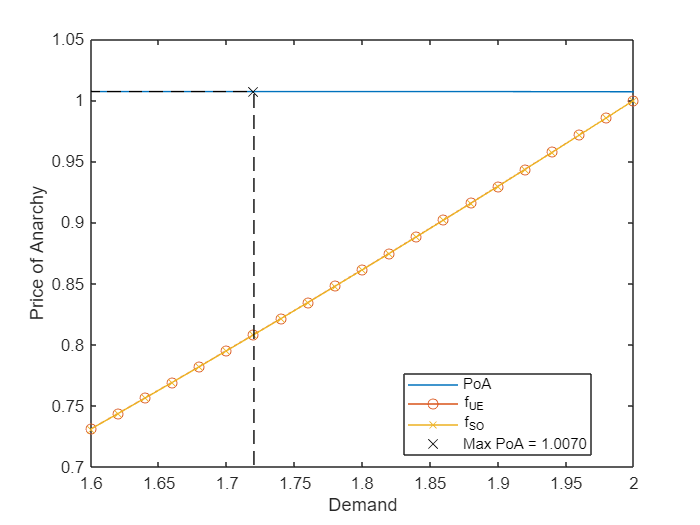

% plot PoA
figure()
plot(dValues, PoA_arr)
xlabel("Demand")
ylabel("Price of Anarchy")
hold on;

%normalise SC and UE
ue_cost_normalized = Sys_Cost(:,1) / max(Sys_Cost(:,1));
so_cost_normalized = Sys_Cost(:,2) / max(Sys_Cost(:,2));
plot(dValues, ue_cost_normalized, marker="o")
hold on;
plot(dValues, so_cost_normalized, marker = "x")

% Highlight maximum PoA and corresponding demand
[maxPoA, maxIdx] = max(PoA_arr); % Find the maximum PoA and its index
maxDemand = dValues(maxIdx);     % Find the corresponding demand value
plot(maxDemand, maxPoA, 'kx', 'MarkerSize', 8, 'DisplayName', 'Max PoA');
plot([maxDemand, maxDemand], [0, maxPoA], 'k--');
plot([0, maxDemand], [maxPoA, maxPoA], 'k--');
xlim([dValues(1), dValues(end)]);
ylim([0.7,1.05]);
legend('PoA', 'f_{UE}', 'f_{SO}', sprintf('Max PoA = %.4f', maxPoA), 'Location', 'best');

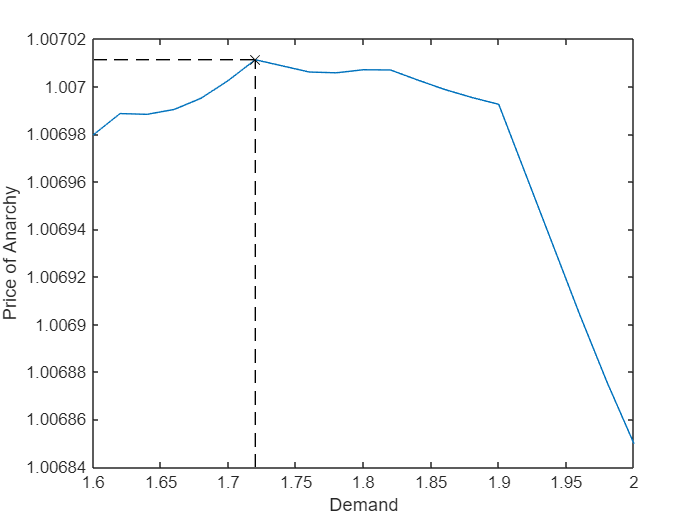


% another figure with just PoA on it 
figure()
plot(dValues, PoA_arr)
xlabel("Demand")
ylabel("Price of Anarchy")
hold on;
plot(maxDemand, maxPoA, 'kx', 'MarkerSize', 8, 'DisplayName', 'Max PoA');
plot([maxDemand, maxDemand], [0, maxPoA], 'k--');
plot([0, maxDemand], [maxPoA, maxPoA], 'k--');
xlim([dValues(1), dValues(end)]);
ylim([1.00684, 1.00702]);
hold off;

The peak price of anarchy was found to be 1.007 and it occured at demand = 1.70. As shown in the figure above. It is interesting to note that the Price of Anarchy is very low. Does the price of anarchy ever go below 1?

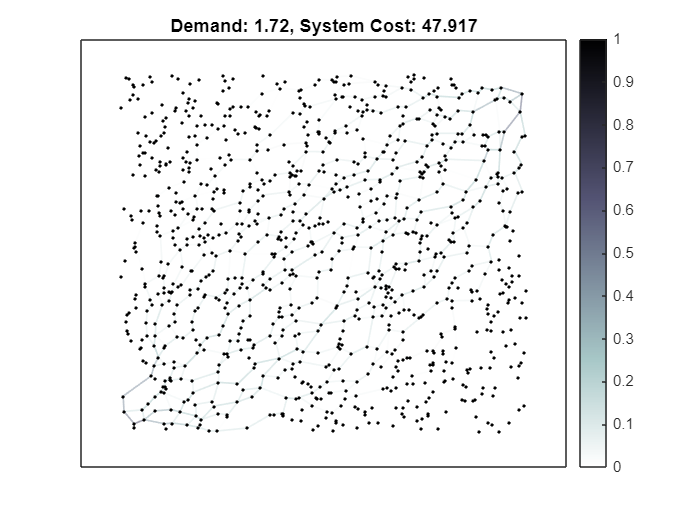

% figures comparing UE and SO
figure;ax=axes;
plotNetwork(G, linkFlows(:, maxIdx, 1), nodeCoordinates, ax);  
title(['Demand: ', num2str(dValues(maxIdx)), ', System Cost: ', num2str(Sys_Cost(maxIdx, 1))]);

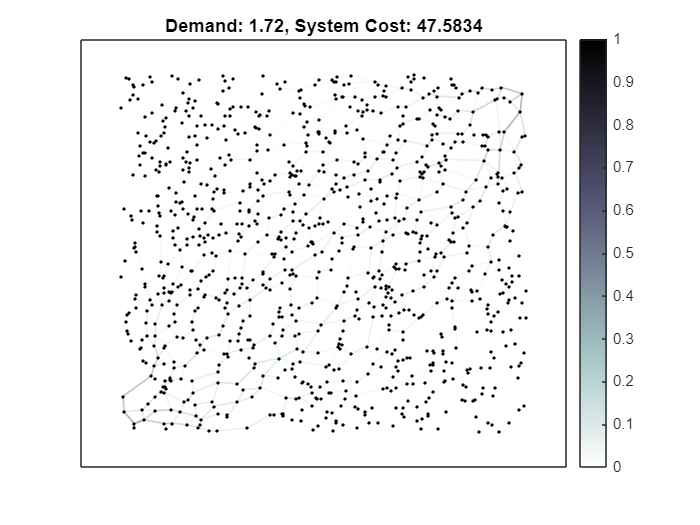

figure;ax=axes;
plotNetwork(G, linkFlows(:, maxIdx, 2), nodeCoordinates, ax); 
title(['Demand: ', num2str(dValues(maxIdx)), ', System Cost: ', num2str(Sys_Cost(maxIdx, 2))]);